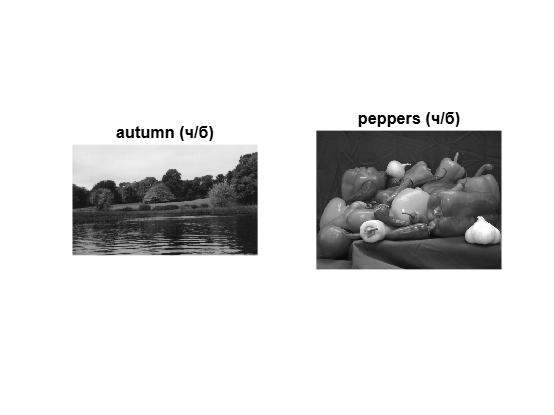

% Завантаження стандартних зображень з бібліотеки MATLAB
color_img1 = imread('autumn.tif'); % Кольорове зображення
color_img2 = imread('peppers.png'); % Додаткове кольорове зображення
gray_img = imread('cameraman.tif'); % Чорно-біле зображення

% Перетворення кольорових зображень у градації сірого
gray_img1 = rgb2gray(color_img1);
gray_img2 = rgb2gray(color_img2);

% Відображення результатів
figure;
subplot(1,2,1), imshow(gray_img1), title('autumn (ч/б)');
subplot(1,2,2), imshow(gray_img2), title('peppers (ч/б)');

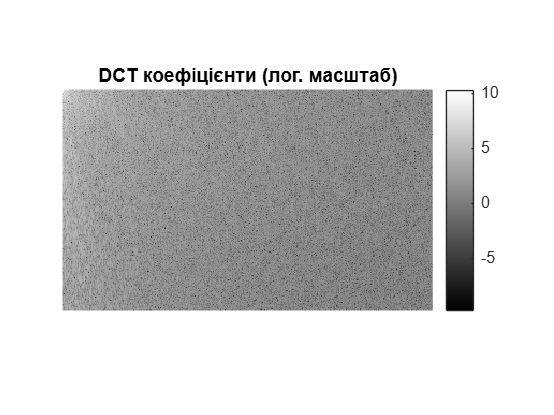


% Застосування DCT до чорно-білого зображення
dct_coeff = dct2(gray_img1);

% Відображення DCT у логарифмічному масштабі
figure;
imshow(log(abs(dct_coeff)), []), colorbar, title('DCT коефіцієнти (лог. масштаб)');

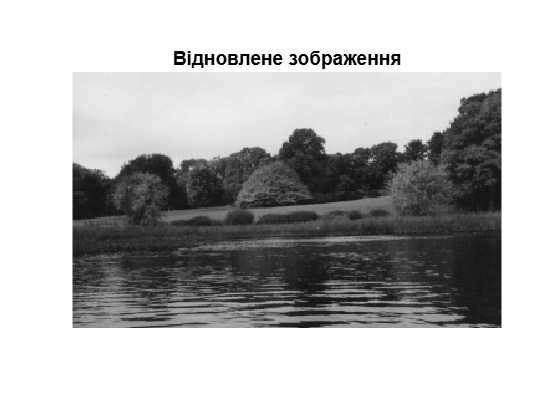


% Відновлення зображення
reconstructed_img = idct2(dct_coeff);

% Відображення результату
figure;
imshow(reconstructed_img, [0 255]), title('Відновлене зображення');

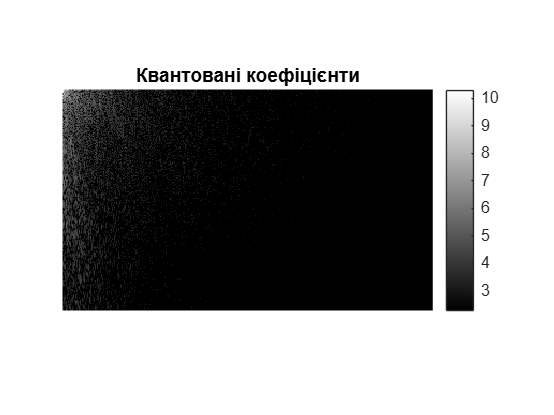


% Крок квантування (експериментуйте зі значеннями)
N = 10; 

% Квантування
quantized_dct = N * round(dct_coeff / N);

% Відображення квантованих коефіцієнтів
figure;
imshow(log(abs(quantized_dct)), []), colorbar, title('Квантовані коефіцієнти');

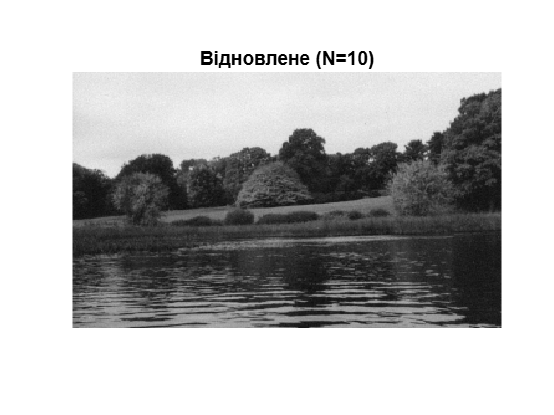


% Відновлення з квантованих коефіцієнтів
quantized_reconstructed = idct2(quantized_dct);

% Відображення
figure;
imshow(quantized_reconstructed, [0 255]), title(['Відновлене (N=', num2str(N), ')']);

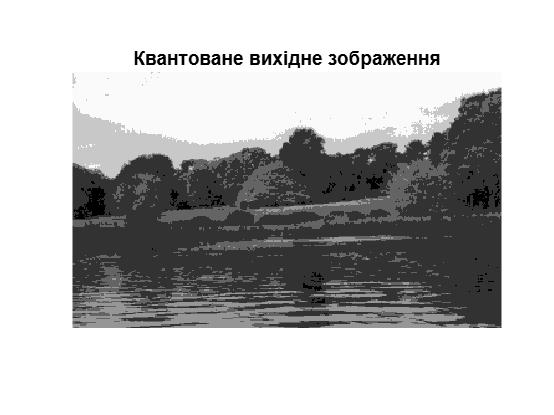


% Квантування вихідного зображення (не DCT)
n = 50; % Крок квантування
quantized_original = n * round(double(gray_img1) / n);

% Відображення
figure;
imshow(uint8(quantized_original)), title('Квантоване вихідне зображення');